## Logistic map

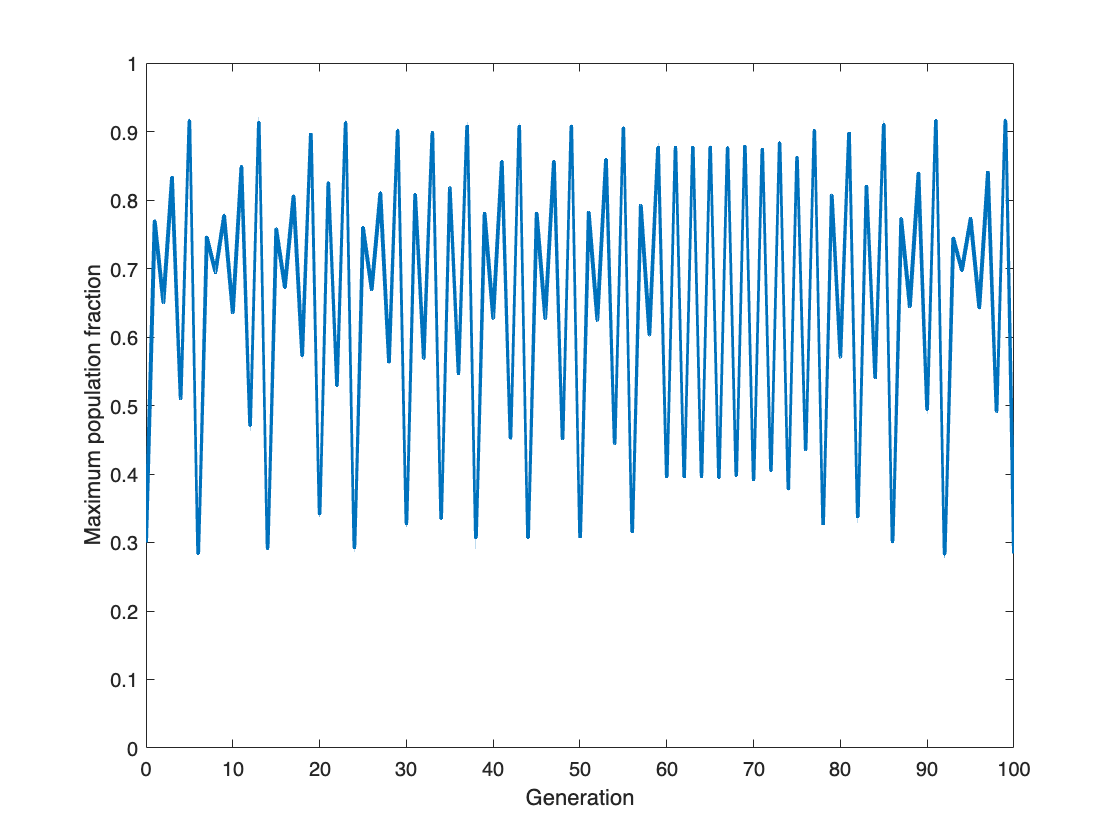

% Set the parameters
  % Growth rate
    r = 3.662;  
    
  % Initial population size (as fraction of maximal population)
    x0 = 0.3;  

  % Number of generations to calculate
     n = 100; 

% Create empty vector for results
x = zeros(n+1, 1);

% Set inital size
x(1) = x0;

for i = 1:n
    x(i+1) = r*(1 - x(i))*x(i);
end

% Plot the results
plot(0:n, x, LineWidth=2);
xlabel('Generation');
ylabel('Maximum population fraction');
ylim([0,1])